clc;
clear;

% 设定步行参数
step_length = 0.2;  % 单脚步长
body_width = 0.205; % 脚印的宽度
z_c = 0.6;          % 质心的高度

% 指定一些参数
T_step = 1.25;      % 单步周期
T_dsp = 0.26;       % 双脚支撑期长度
dt = 0.01;          % 采样间隔

N = round(T_step/dt);   % 单步采样数
n = round(T_dsp /dt);   % 单步双脚支撑期采样数

a = 10;     % 修正落脚点用的参数
b = 1;      % 修正落脚点用的参数

g = 9.81;           % 重力加速度
Tc = sqrt(z_c/g);   % 时间常数，见LIPM公式
C = cosh(T_step/Tc);    % 减少计算量
S = sinh(T_step/Tc);    % 减少计算量


% 设定步行单元
% 脚印位置
s_x = [0.0,         step_length,    step_length,    step_length,    step_length, step_length, step_length, step_length, 0.0];
s_y = [body_width,  body_width,     body_width,     body_width,     body_width,  body_width,  body_width,  body_width,  body_width];
s_theta = [0, 30, 60, 90, 120, 150, 180, 210, 240] / 360 * (2 * pi);

% 步数
step = size(s_x, 2);    

% 设置中间变量的容器
% 设置的落脚点位置，即每步的ZMP参考点
p_x = zeros([1,step]);
p_y = zeros([1,step]);

%  
x_bar = zeros([1,step-1]);
y_bar = zeros([1,step-1]);
vx_bar = zeros([1,step-1]);
vy_bar = zeros([1,step-1]);

% 
x_d = zeros([1,step-1]);
vx_d = zeros([1,step-1]);
y_d = zeros([1,step-1]);
vy_d = zeros([1,step-1]);

% 修正后的落脚点，用于实际实施的LIPM计算
p_x_star = zeros([1,step-1]);
p_y_star = zeros([1,step-1]);

% 单脚支撑期数据（0～N）
ssp_x_route = zeros([N+1,step-1]);
ssp_vx_route = zeros([N+1,step-1]);
ssp_ax_route = zeros([N+1,step-1]);
ssp_y_route = zeros([N+1,step-1]);
ssp_vy_route = zeros([N+1,step-1]);
ssp_ay_route = zeros([N+1,step-1]);

% 双脚支撑期数据（0～N）
dsp_x_route = zeros([N+1,step-1]);
dsp_vx_route = zeros([N+1,step-1]);
dsp_ax_route = zeros([N+1,step-1]);
dsp_y_route = zeros([N+1,step-1]);
dsp_vy_route = zeros([N+1,step-1]);
dsp_ay_route = zeros([N+1,step-1]);

% 初始条件，质心的位置、速度和ZMP的初始位置
x_ini = 0;
vx_ini = 0;

y_ini = body_width / 2;
vy_ini = 0;

p_x(1) = 0;
p_y(1) = -body_width / 2;

% 主循环
for i=1:step-1
    % Step 5 计算下一个落脚点
    % p_x(i+1) = p_x(i) + s_x(i);
    % p_y(i+1) = p_y(i) - (-1)^i * s_y(i);

    p_x(i+1) = p_x(i) + cos(s_theta(i)) * s_x(i) + sin(s_theta(i)) * (-1)^i * s_y(i);
    p_y(i+1) = p_y(i) + sin(s_theta(i)) * s_x(i) - cos(s_theta(i)) * (-1)^i * s_y(i);

    % Step 6 最后一步的质心位置和质心速度
    x_bar(i) = s_x(i+1)/2;
    y_bar(i) = (-1)^(i) * s_y(i+1)/2;
    vx_bar(i) = (C+1)/(Tc*S) * x_bar(i);
    vy_bar(i) = (C-1)/(Tc*S) * y_bar(i);

    % Step 7 
    x_d(i) = p_x(i+1) + x_bar(i);
    vx_d(i) = vx_bar(i);
    y_d(i) = p_y(i+1) + y_bar(i);
    vy_d(i) = vy_bar(i);

    % Step 8 修正落脚点（优化问题求解）
    D = a*(C-1)^2 + b*(S/Tc)^2;
    p_x_star(i) = -a*(C-1)/D * (x_d(i) - C*x_ini - Tc*S*vx_ini) - b*S/(Tc*D) * (vx_d(i) - S/Tc * x_ini - C*vx_ini);
    p_y_star(i) = -a*(C-1)/D * (y_d(i) - C*y_ini - Tc*S*vy_ini) - b*S/(Tc*D) * (vy_d(i) - S/Tc * y_ini - C*vy_ini); 

    % Step 3 代入到LIPM的方程之中得到单足支撑期结束时的状态
    x_ssp = (x_ini - p_x_star(i)) * cosh(T_step/Tc) + Tc * vx_ini * sinh(T_step/Tc) + p_x_star(i);
    vx_ssp = (x_ini - p_x_star(i))/Tc * sinh(T_step/Tc) + vx_ini * cosh(T_step/Tc);
    y_ssp = (y_ini - p_y_star(i)) * cosh(T_step/Tc) + Tc * vy_ini * sinh(T_step/Tc) + p_y_star(i);
    vy_ssp = (y_ini - p_y_star(i))/Tc * sinh(T_step/Tc) + vy_ini * cosh(T_step/Tc);

    % 得到过程中的点位置，第一步都是单脚支撑
    for j=0:N
        ssp_x_route(j+1,i) = (x_ini - p_x_star(i)) * cosh(j*dt/Tc) + Tc * vx_ini * sinh(j*dt/Tc) + p_x_star(i);
        ssp_vx_route(j+1,i) = (x_ini - p_x_star(i))/Tc * sinh(j*dt/Tc) + vx_ini * cosh(j*dt/Tc);
        ssp_ax_route(j+1,i) = (x_ini - p_x_star(i))/Tc.^2 * cosh(j*dt/Tc) + vx_ini * sinh(j*dt/Tc)/Tc;

        ssp_y_route(j+1,i) = (y_ini - p_y_star(i)) * cosh(j*dt/Tc) + Tc * vy_ini * sinh(j*dt/Tc) + p_y_star(i);
        ssp_vy_route(j+1,i) = (y_ini - p_y_star(i))/Tc * sinh(j*dt/Tc) + vy_ini * cosh(j*dt/Tc);
        ssp_ay_route(j+1,i) = (y_ini - p_y_star(i))/Tc.^2 * cosh(j*dt/Tc) + vy_ini * sinh(j*dt/Tc)/Tc;
    end

    % 更新初始条件
    x_ini = x_ssp;
    vx_ini = vx_ssp;
    y_ini = y_ssp;
    vy_ini = vy_ssp;
end

% 差值（五次样条）获得双脚支撑时的数据
dsp_x_route = ssp_x_route;
dsp_vx_route = ssp_vx_route;
dsp_ax_route = ssp_ax_route;

dsp_y_route = ssp_y_route;
dsp_vy_route = ssp_vy_route;
dsp_ay_route = ssp_ay_route;

for i=1:step-2
    dsp_ini_x = ssp_x_route(N+1-n/2, i);
    dsp_ini_vx = ssp_vx_route(N+1-n/2, i);
    dsp_ini_ax = ssp_ax_route(N+1-n/2, i);
    dsp_eos_x = ssp_x_route(n/2+1, i+1);
    dsp_eos_vx = ssp_vx_route(n/2+1, i+1);
    dsp_eos_ax = ssp_ax_route(n/2+1, i+1);

    boundMat = [dsp_ini_x; dsp_ini_vx; dsp_ini_ax; dsp_eos_x; dsp_eos_vx; dsp_eos_ax];
    Pmat(1, :) = [-6.0/(T_dsp^5), -3.0/(T_dsp^4), -1.0/(2*T_dsp^3), 6.0/(T_dsp^5), -3.0/(T_dsp^4), 1.0/(2*T_dsp^3) ];
    Pmat(2, :) = [15.0/(T_dsp^4), 8.0/(T_dsp^3), 3.0/(2*T_dsp^2), -15.0/(T_dsp^4), 7.0/(T_dsp^3), -2.0/(2*T_dsp^2) ];
    Pmat(3, :) = [-10.0/(T_dsp^3), -6.0/(T_dsp^2), -3.0/(2*T_dsp), 10.0/(T_dsp^3), -4.0/(T_dsp^2), 1.0/(2*T_dsp) ];
    Pmat(4, :) = [0, 0, 0.5, 0, 0, 0];
    Pmat(5, :) = [0, 1, 0, 0, 0, 0];
    Pmat(6, :) = [1, 0, 0, 0, 0, 0];
    Px = Pmat*boundMat;

    dsp_ini_y = ssp_y_route(N+1-n/2, i);
    dsp_ini_vy = ssp_vy_route(N+1-n/2, i);
    dsp_ini_ay = ssp_ay_route(N+1-n/2, i);
    dsp_eos_y = ssp_y_route(n/2+1, i+1);
    dsp_eos_vy = ssp_vy_route(n/2+1, i+1);
    dsp_eos_ay = ssp_ay_route(n/2+1, i+1);

    boundMat = [dsp_ini_y; dsp_ini_vy; dsp_ini_ay; dsp_eos_y; dsp_eos_vy; dsp_eos_ay];
    Pmat(1, :) = [-6.0/(T_dsp^5), -3.0/(T_dsp^4), -1.0/(2*T_dsp^3), 6.0/(T_dsp^5), -3.0/(T_dsp^4), 1.0/(2*T_dsp^3) ];
    Pmat(2, :) = [15.0/(T_dsp^4), 8.0/(T_dsp^3), 3.0/(2*T_dsp^2), -15.0/(T_dsp^4), 7.0/(T_dsp^3), -2.0/(2*T_dsp^2) ];
    Pmat(3, :) = [-10.0/(T_dsp^3), -6.0/(T_dsp^2), -3.0/(2*T_dsp), 10.0/(T_dsp^3), -4.0/(T_dsp^2), 1.0/(2*T_dsp) ];
    Pmat(4, :) = [0, 0, 0.5, 0, 0, 0];
    Pmat(5, :) = [0, 1, 0, 0, 0, 0];
    Pmat(6, :) = [1, 0, 0, 0, 0, 0];
    Py = Pmat*boundMat;

    for j=1:n+1
        t_s = (j-1)*dt;
        time_vec = [t_s^5, t_s^4, t_s^3, t_s^2, t_s, 1];
        v_time_vec = [5*(t_s^4), 4*(t_s^3), 3*(t_s^2), 2*t_s, 1, 0];
        a_time_vec = [20*(t_s^3), 12*(t_s^2), 6*t_s, 2, 0, 0];
        if j <= n/2 + 1
            dsp_x_route(N-n/2+j, i) = time_vec * Px;
            dsp_y_route(N-n/2+j, i) = time_vec * Py;
            dsp_vx_route(N-n/2+j, i) = v_time_vec * Px;
            dsp_vy_route(N-n/2+j, i) = v_time_vec * Py;
            dsp_ax_route(N-n/2+j, i) = a_time_vec * Px;
            dsp_ay_route(N-n/2+j, i) = a_time_vec * Py;
        else
            dsp_x_route(j-n/2, i+1) = time_vec * Px;
            dsp_y_route(j-n/2, i+1) = time_vec * Py;
            dsp_vx_route(j-n/2, i+1) = v_time_vec * Px;
            dsp_vy_route(j-n/2, i+1) = v_time_vec * Py;
            dsp_ax_route(j-n/2, i+1) = a_time_vec * Px;
            dsp_ay_route(j-n/2, i+1) = a_time_vec * Py;
        end
        dsp_x_route(1, i+1) = dsp_x_route(N+1, i);
        dsp_y_route(1, i+1) = dsp_y_route(N+1, i);
        dsp_vx_route(1, i+1) = dsp_vx_route(N+1, i);
        dsp_vy_route(1, i+1) = dsp_vy_route(N+1, i);
        dsp_ax_route(1, i+1) = dsp_ax_route(N+1, i);
        dsp_ay_route(1, i+1) = dsp_ay_route(N+1, i);
    end
end

dsp_px_route = dsp_x_route - z_c/g * dsp_ax_route;
dsp_py_route = dsp_y_route - z_c/g * dsp_ay_route;

t_total = (size(ssp_x_route(:))-1)*dt;
t = 0:dt:t_total;

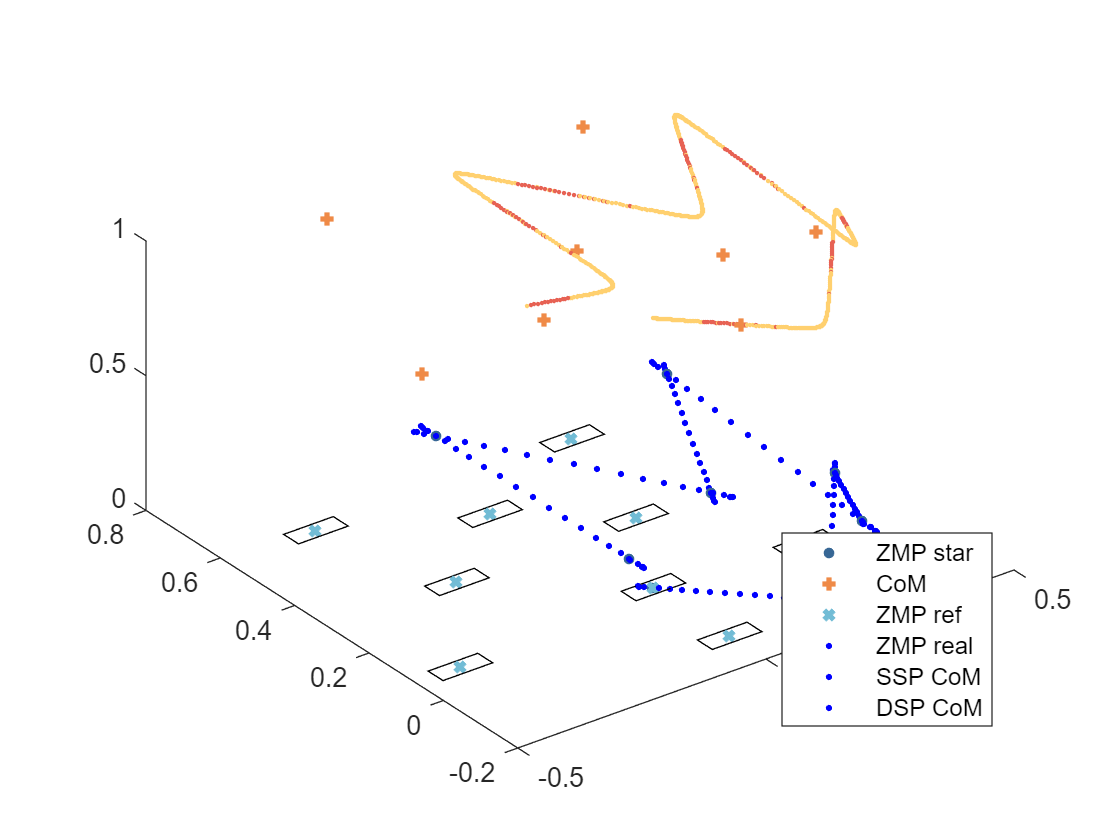

% 绘图部分
% 设置基础颜色
colors = [55, 103, 149; 114, 188, 213; 255, 208, 111; 231, 98, 84; 239, 138, 71];
color1 = colors(1, :) / 255;
color2 = colors(2, :) / 255;
color3 = colors(3, :) / 255;
color4 = colors(4, :) / 255;
color5 = colors(5, :) / 255;

figure();
hold on;
plot3(p_x_star,p_y_star,zeros(size(p_x_star)),'.', 'Color', color1, 'MarkerSize', 12);
plot3(x_d, y_d,ones(size(x_d)), '+', 'Color', color5, 'MarkerSize', 5, 'LineWidth', 2);
plot3(p_x, p_y,zeros(size(p_x)),'x', 'Color', color2, 'MarkerSize', 5, 'LineWidth', 2);

for i=1:size(p_x,2)
    rectangle('Position',[p_x(i)-0.05,p_y(i)-0.02,0.1,0.04]);
end
plot3(dsp_px_route, dsp_py_route,zeros(size(dsp_px_route)), '.', 'Color', 'b', 'MarkerSize', 7)
plot3(ssp_x_route(:), ssp_y_route(:), ones(size(ssp_x_route(:))), '.', 'Color', color3, 'MarkerSize', 5);
for i = 1 : step-1 
    for j=1:N
        if j<= (n+2)/2 || j >= N-n/2+1
            plot3(dsp_x_route(j,i), dsp_y_route(j,i),1, '.', 'Color', color4, 'MarkerSize', 5);
        end
    end
end
legend({'ZMP star','CoM','ZMP ref','ZMP real','SSP CoM','DSP CoM'},'Location','southeast')
view([-36.843 47.775])

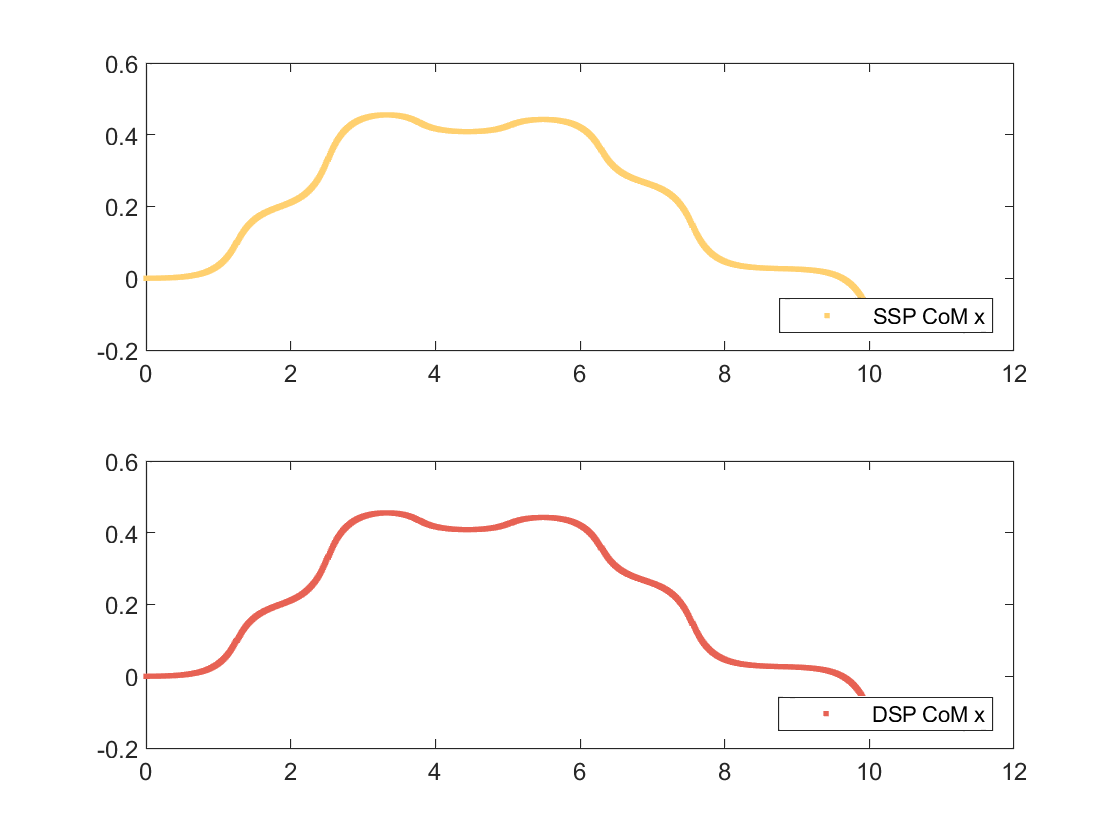

figure();
hold on;
subplot(2,1,1);
plot(t, ssp_x_route(:), '.', 'Color', color3, 'LineWidth', 2)
legend({'SSP CoM x'},'Location','southeast')
subplot(2,1,2);
plot(t, dsp_x_route(:), '.', 'Color', color4, 'LineWidth', 2)
legend({'DSP CoM x'},'Location','southeast')

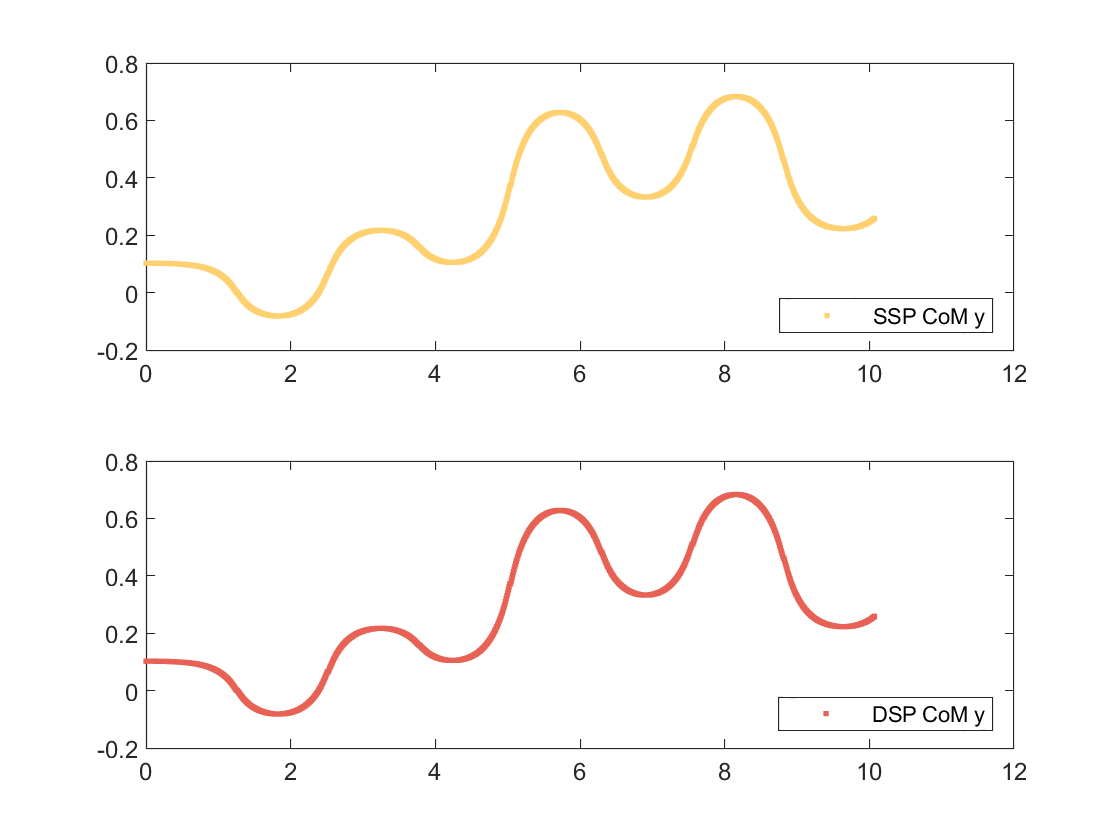

figure();
hold on;
subplot(2,1,1);
plot(t, ssp_y_route(:), '.', 'Color', color3, 'LineWidth', 2)
legend({'SSP CoM y'},'Location','southeast')
subplot(2,1,2);
plot(t, dsp_y_route(:), '.', 'Color', color4, 'LineWidth', 2)
legend({'DSP CoM y'},'Location','southeast')

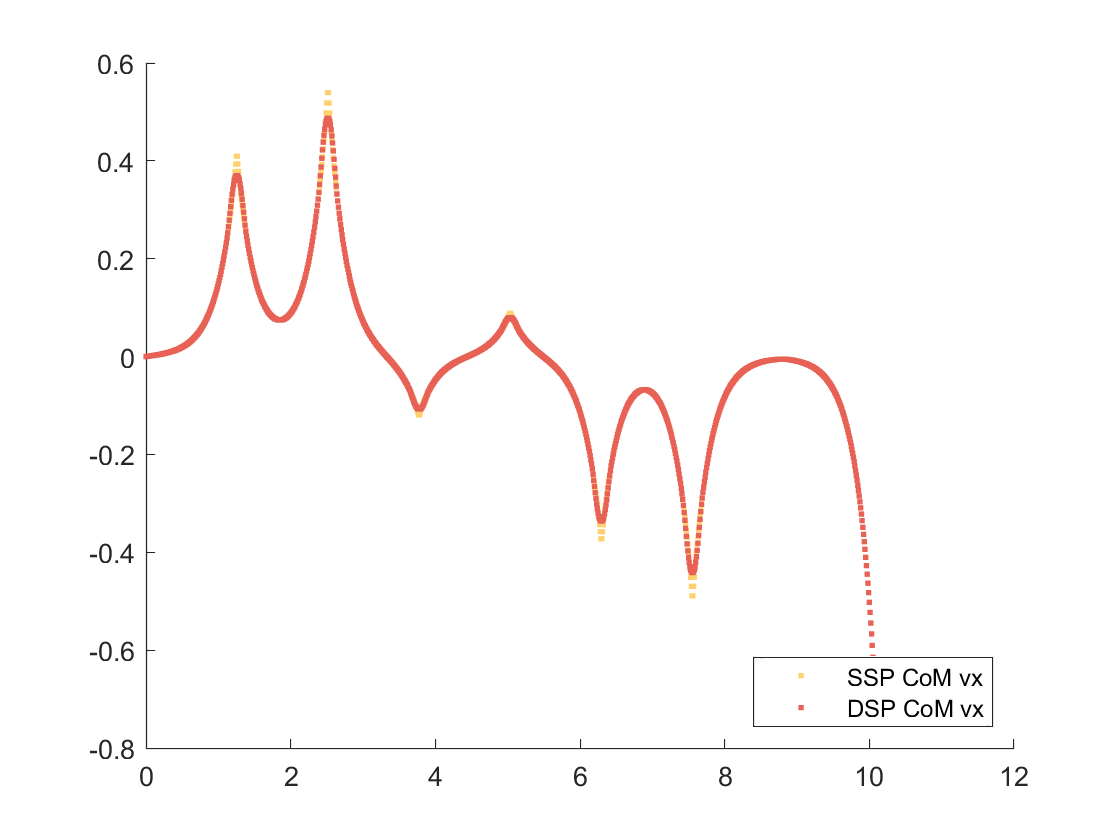

figure();
hold on;
plot(t, ssp_vx_route(:), '.', 'Color', color3, 'LineWidth', 1)
plot(t, dsp_vx_route(:), '.', 'Color', color4, 'LineWidth', 1)
legend({'SSP CoM vx','DSP CoM vx'},'Location','southeast')

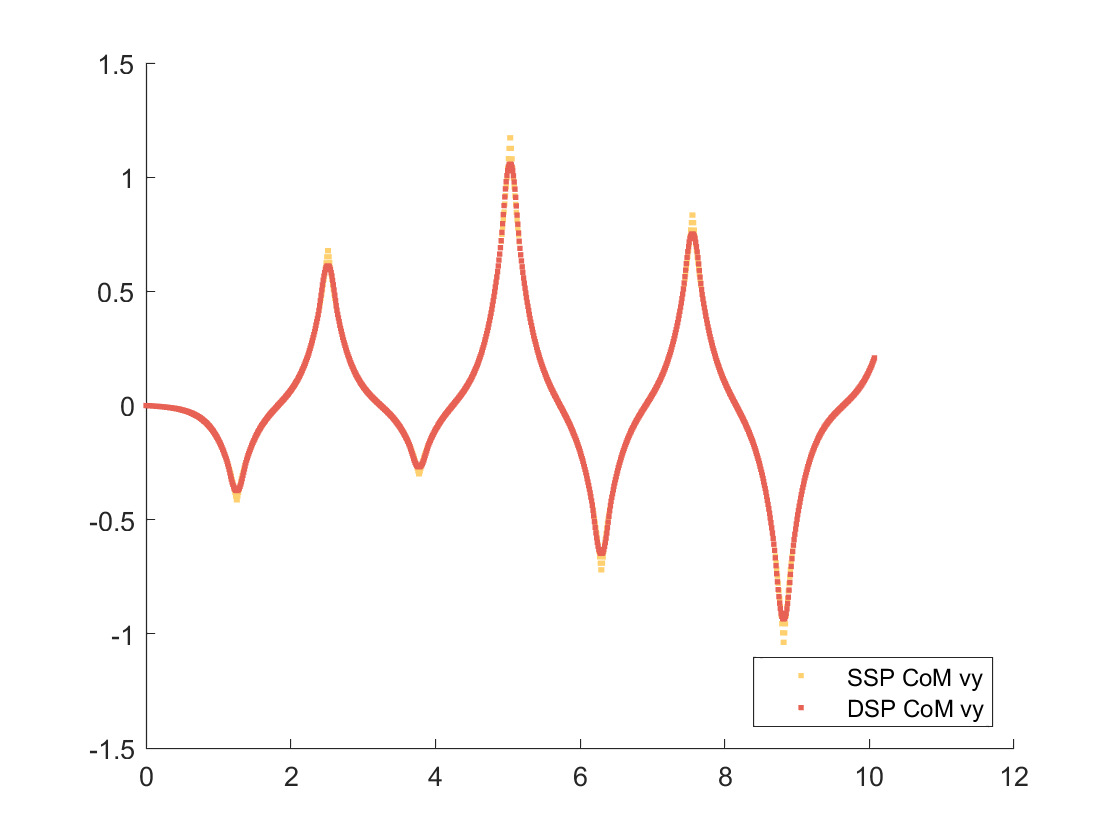

figure();
hold on;
plot(t, ssp_vy_route(:), '.', 'Color', color3, 'LineWidth', 1)
plot(t, dsp_vy_route(:), '.', 'Color', color4, 'LineWidth', 1)
legend({'SSP CoM vy','DSP CoM vy'},'Location','southeast')

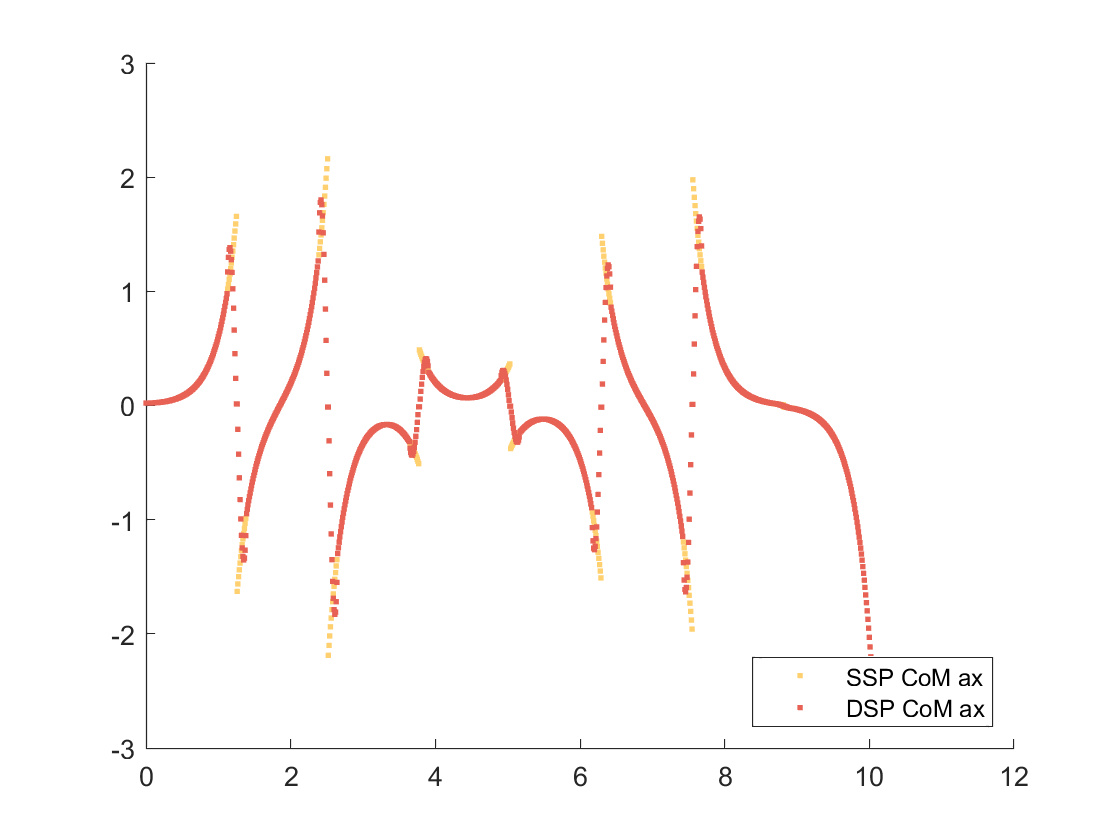

figure();
hold on;
plot(t, ssp_ax_route(:), '.', 'Color', color3, 'LineWidth', 1)
plot(t, dsp_ax_route(:), '.', 'Color', color4, 'LineWidth', 1)
legend({'SSP CoM ax','DSP CoM ax'},'Location','southeast')

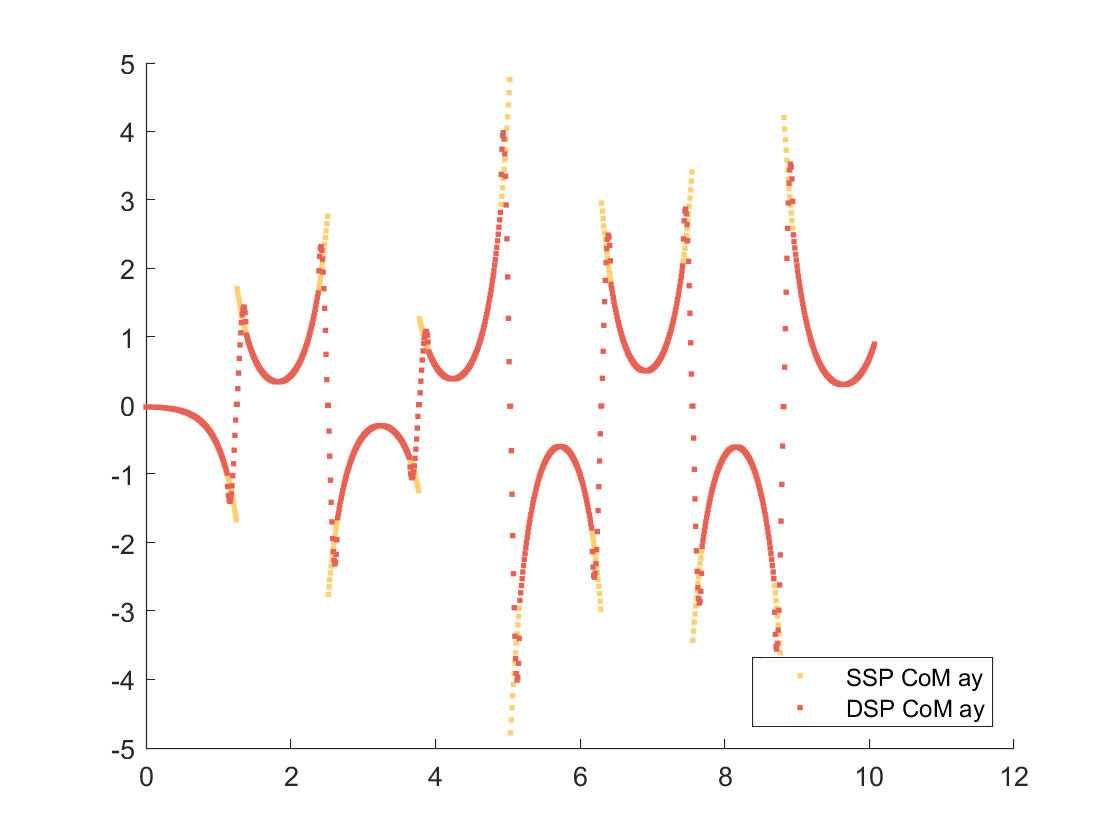

figure();
hold on;
plot(t, ssp_ay_route(:), '.', 'Color', color3, 'LineWidth', 1)
plot(t, dsp_ay_route(:), '.', 'Color', color4, 'LineWidth', 1)
legend({'SSP CoM ay','DSP CoM ay'},'Location','southeast')